# COVID19 - DETECCIÓN DE MASCARILLA

## Flujo de Trabajo para la automatización del etiquetado

Etiqueta de imagen con algoritmo de automatización 

Prototipo con imagenes de 

imds = imageDatastore("SampleMaskData\")

imds =   ImageDatastore - 속성 있음:

                       Files: {
                              ' ...\COVID_Project\mask\FEX_Submission\SampleMaskData\a01.jpg';
                              ' ...\COVID_Project\mask\FEX_Submission\SampleMaskData\a02.jpg';
                              ' ...\COVID_Project\mask\FEX_Submission\SampleMaskData\a03.jpg'
                               ... and 5 more
                              }
                     Folders: {
                              ' ...\Demos\Deep Learning\COVID_Project\mask\FEX_Submission\SampleMaskData'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


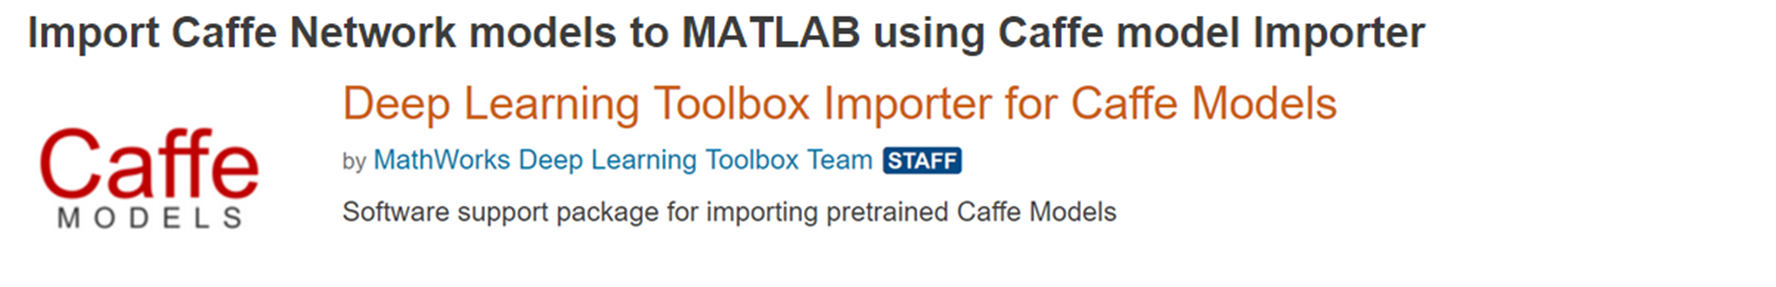

Descargue el modelo Caffe y el archivo proto para la detección de rostros 

modelFolder = 'models';
if ~isfolder('models')
    mkdir(modelFolder)
end
modelFaceYolo = 'net_face_yolo';
if ~isfile(fullfile(modelFolder,[modelFaceYolo,'.mat']))
    fprintf(1,'Downloading Caffe model for face detection...');
    netFaceYoloModelFilename = websave(fullfile(modelFolder,[modelFaceYolo,'.caffemodel']), ...
        'http://www.abars.biz/keras/face.caffemodel');
    netFaceYoloProtoFilename = websave(fullfile(modelFolder,[modelFaceYolo,'_deploy.prototxt']), ...
        'http://www.abars.biz/keras/face.prototxt');
    fprintf(1,'[DONE]\n')
end

Prepare la red de detección de rostros en formato MATLAB 

doImportandSave = false;
if doImportandSave
    faceYoloNet = importCaffeNetwork('models\net_face_yolo_deploy.prototxt', ...
        'models\net_face_yolo.caffemodel','OutputLayerType','regression');
    save models\net_face_yolo.mat faceYoloNet
end

Leer imagen de muestra 

img = read(imds);
ori_sz = size(img, [1 2]);
re_sz = [448 448];
imgr = imresize(img, re_sz);
scale = ori_sz./re_sz;

Cambiar la escala del cuadro delimitador con respecto a la imagen original

bbox = predictFace(imgr, 'models\net_face_yolo.mat');

Suponga que la mitad inferior podría ser la máscara. **OJO**

bbox(:,4) = bbox(:,4)./2+20;
bbox(:,2) = bbox(:,2)+bbox(:,4)-20;
bbox(:,3) = bbox(:,3)+20;
bbox = bboxresize(round(bbox),scale);

Dibuja el cuadro delimitador devuelto alrededor de la cara detectada.

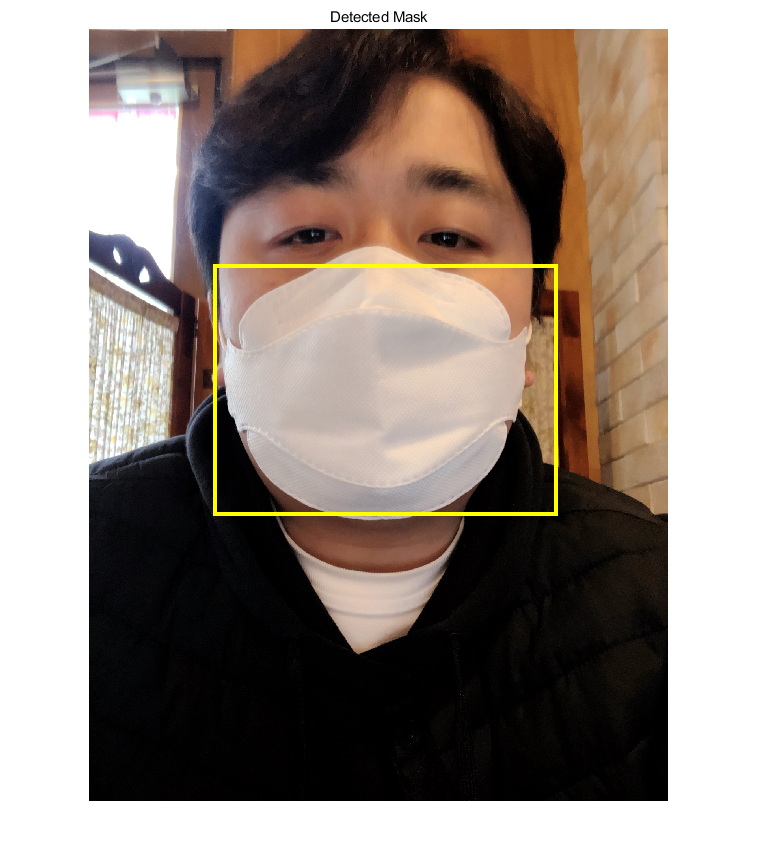

img = insertShape(img, 'Rectangle', bbox, 'LineWidth', 15);
figure; imshow(img); title('Detected Mask');

#### Automaticemos esto

imageLabeler

*Copyright 2020 The MathWorks, Inc.*